%una empresa de lacteos ciledco tiene necesita acelerar su
%produccion de leche en la cual se describe el proceso
%mediante la siguiente funcion de transferencia
%G1=40/(s+2)*(s+10)
%en donde se debe tardar menos de 2.5seg la rapidez de produccion
%de leche del tanque que que tiene un tope del 800l el cual debe
%tener un sobresalto de ese tope de un 10% mas para sacar mas
%botellas de leche y un error de llenado de estas bottellas de
%un 0 para que el proceso sea lo mas eficiente posible
%DATOS:ep=0;mp<10%;ts<2.5seg
s=tf('s');
G1=40/(s*((s+2)*(s+10)))

G1 =
 
          40
  -------------------
  s^3 + 12 s^2 + 20 s
 
Continuous-time transfer function.



Mp=0.10;
ts=2.5;
zeta=-log(Mp)/(sqrt(pi^2+log(Mp)^2))

zeta = 0.5912

wn=4/(zeta*ts)

wn = 2.7066

wd=wn*sqrt(1-zeta^2)

wd = 2.1830

sigma=4/ts

sigma = 1.6000

z=sigma;
p=z+5;
sx=-sigma+wd*i

sx = -1.6000 + 2.1830i

Gx=40/(sx*((sx+2)*(sx+10)))

Gx = -0.5841 + 0.4975i

cx=(sx+z)/(sx+p);
kc=1/(abs(Gx)*abs(cx))

kc = 3.2573

c=zpk(-z,-p,kc)

c =
 
  3.2573 (s+1.6)
  --------------
     (s+6.6)
 
Continuous-time zero/pole/gain model.



FT=feedback(c*G1,1)

FT =
 
                130.29 (s+1.6)
  ------------------------------------------
  (s+12.06) (s+1.268) (s^2 + 5.273s + 13.63)
 
Continuous-time zero/pole/gain model.



stepinfo(FT)

ans = struct with fields:
        RiseTime: 0.8274
    SettlingTime: 2.3086
     SettlingMin: 0.9110
     SettlingMax: 0.9998
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9998
        PeakTime: 5.9036


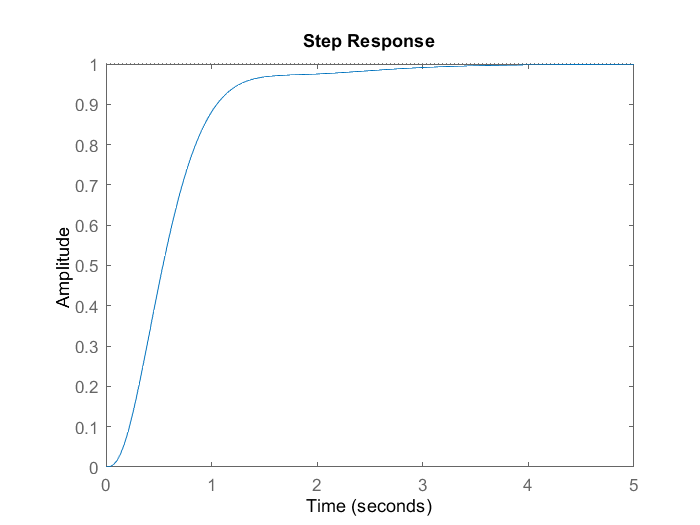

step(FT)